# Bridge of Doom

parametric equation: r(u) = 4*(.396cos(2.65(u+1.4))i - .99sin(u+1.4)j), u in set [0, 3.2]

clc, clear all

syms u

ri = 4*0.396*cos(2.65*(u + 1.4));
rj = 4*-0.99*sin(u + 1.4);
rk = 4*0*u;
r=[ri,rj,rk];

dr=diff(r,u);

assume(u,{'real','positive'})

T_hat=simplify(dr./norm(dr))

dT_hat=diff(T_hat,u);

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(u+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$

N_hat=simplify(dT_hat/norm(dT_hat))

B_hat=simplify(cross(T_hat,N_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(483625\,\sigma_{6}+702250\,\sigma_{5}+218625\,\sigma_{4}\right)}{\sigma_{1}} & \frac{561800\,\sin\left(u+\frac{7}{5}\right)+1025285\,\sigma_{3}+463485\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=265\,\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}+2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{20}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right) \end{array}$$


kappa=simplify(norm(dT_hat)/norm(dr))

$$B\_hat = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{91250\,\cos\left(\frac{7\,u}{20}+\frac{49}{100}\right)+\frac{764917\,\cos\left(\frac{33\,u}{20}+\frac{231}{100}\right)}{2}+\frac{327837\,\cos\left(\frac{73\,u}{20}+\frac{511}{100}\right)}{2}+41250\,\cos\left(\frac{113\,u}{20}+\frac{791}{100}\right)-\frac{205057\,\cos\left(\frac{139\,u}{20}+\frac{973}{100}\right)}{2}-\frac{92697\,\cos\left(\frac{179\,u}{20}+\frac{1253}{100}\right)}{2}}{\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\right)}^{2}+2500\,{\left(73\,\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\right)}^{2}}\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{53\,u}{20}+\frac{371}{100} \end{array}$$


tau=-N_hat*(diff(B_hat,u)/norm(dr))'

$$kappa = \begin{array}{l} \frac{165625\,\sqrt{2}\,\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\right)}^{2}+2500\,{\left(73\,\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\right)}^{2}}}{198\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}\,{\left(2500\,\cos\left(2\,u+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{10}+\frac{371}{50}\right)+5309\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{53\,u}{20}+\frac{371}{100} \end{array}$$


u_num = linspace(0,3.2,100); 

$$tau = 0$$


for n=1:length(u_num)
    r_num(n,:)=double(subs(r, u,u_num(n)));
    T_hat_num(n,:)=double(subs(T_hat,u, u_num(n)));
    N_hat_num(n,:)=double(subs(N_hat, u, u_num(n)));
    B_hat_num(n,:)=double(subs(B_hat, u, u_num(n)));
    
end
figure(), clf
hold on
plot3(r_num(:,1),r_num(:,2),r_num(:,3)), axis equal
for n = 1:20:100
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r') % plot the unit tangent
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'b') % plot the unit normal
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),B_hat_num(n,1),B_hat_num(n,2),B_hat_num(n,3),'g')
end
title('Parametric Curve Center Line')
hold off

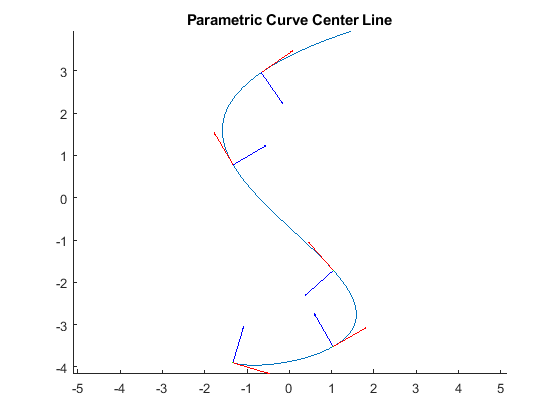

%36.2
syms omega d

omega = simplify(cross(T_hat, dT_hat))
v_R = simplify(norm(dr) + omega(3)*(d/2))
v_L = simplify(norm(dr) - omega(3)*(d/2))


$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{19345\,\cos\left(\frac{33\,u}{20}+\frac{231}{100}\right)+8745\,\cos\left(\frac{73\,u}{20}+\frac{511}{100}\right)}{5000\,\cos\left(2\,u+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,u}{10}+\frac{371}{50}\right)+10618} \end{array}\right)$$

d_num = .235;

$$v\_R = \frac{99\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}}}{1250}-\frac{d\,\left(19345\,\cos\left(\frac{33\,u}{20}+\frac{231}{100}\right)+8745\,\cos\left(\frac{73\,u}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,u+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,u}{10}+\frac{371}{50}\right)+10618\right)}$$

t_num = linspace(0,3.2,100);

$$v\_L = \frac{99\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}}}{1250}+\frac{d\,\left(19345\,\cos\left(\frac{33\,u}{20}+\frac{231}{100}\right)+8745\,\cos\left(\frac{73\,u}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,u+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,u}{10}+\frac{371}{50}\right)+10618\right)}$$

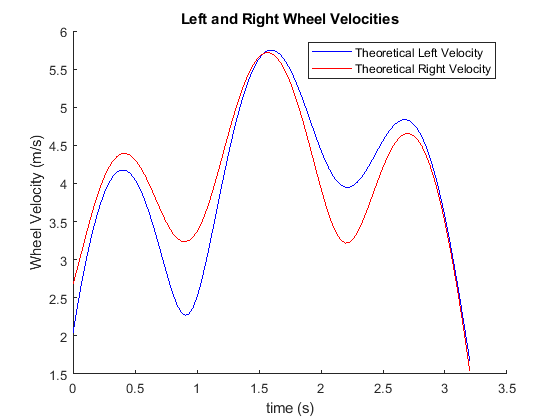

figure(), clf
for n = 1:length(t_num)
    v_left(n) = double(subs(v_L, [u,d], [t_num(n), d_num]));
    v_right(n) = double(subs(v_R, [u,d], [t_num(n), d_num]));

end
hold on
plot(t_num,v_left, 'b')
plot(t_num,v_right, 'r')
title('Left and Right Wheel Velocities')
legend('Theoretical Left Velocity', 'Theoretical Right Velocity')
xlabel('time (s)')
ylabel('Wheel Velocity (m/s)')
hold off
